# Joint Lip Tongue 5-mechanism plus blood search

This is a sequential fitting approach.  It is applied to the full 500-700 nm range.

## Stage 1 (oeSolveJoint).

We fix a matrix with collagen1-smooth, FAD_webfluor, porphyrin and chlorophyll excitations. We choose those because the first two fit the lip data well.  This guarantees that we will be able to find a fit to the lip data at the end.

We use oeSolveJoint to do two things.  

- Vary the blood oxygen of collagen, and 

- Search for one more, additional fluorophore specified only as a skewed Gaussian with three parameters (mean, width, skew).  

The additional fluorophore is a stand-in for keratin, which is present on the tongue, but not on the lip.

In the initial stage of the fit, we use the same blood density for all subjects.  The purpose of this stage is to learn about the parameters of the skewed Gaussian, which we store and use later.

## Stage 2 (oeSolveBlood)

We confirm that we can fit the lip data with just the collagen and FAD, searching for blood.  This is for the group lipData.

## Stage 3 (oeSolveBlood)

We loop through the subjects.  

For the tongue, we use the five fluorophores (collagen, FAD, porphyrin, chlorophyll, pseudo-keratin) and solve for the blood in each subject.

For the lip, we use the two fluorophores (collagen, FAD) and solve for the blood in each subject.

ieInit;
wave = 500:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Load up the lip and tongue data

Here, we load all of the subjects into a single large data set for tongue and another one for lip.

subjects = {'Z','B','D','J'};

% These are the first data we use to find the skewed Gaussian.
tongueData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);
    tongueData = cat(2,tongueData,tmp);
end

% ieFigure; plot(wave,tongueData);


## Create the fixed fluorophores

The first two worked for the lip very well from 500-700nm (see s_oeBloodFluorophoreLipSrch700.mlx).  For the tongue, we add porphyrin and chlorophyl (see s_oeBloodFluorophoreTongueSrch700.mlx).

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor','PorphyrinBjurshammar','chlorophyllA-7'};
[fixedFluorophores,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## Call the joint search

We have fluorophores for the lip that we know can fit if we adjust the blood density for each subject.  Those are collagen1-smooth and FAD_webfluor.  Those are shown to work in s_oeBloodFluorophoreLipSrch700.mlx.

Here, we fix those two fluorophores and fit a first approximation to all the tongue data from all the subjects, getting an approximate extra skewed Gaussian and an overall blood density.  That fit includes porphyrin and chlorophyll.  We save that skewedGaussian as our one extra fluorophore.  We will allow the blood density to vary using those five terms (collagen1-smooth, FAD_webfluor, porphyrin, chlorophyll, skewedG).  

We don't need the last three for the lip. 

When wel use it to fit the tongue data, we apply it to each subject separately to find the blood density for that subject.

[global_params, weights, finalFluorophores] = oeSolveJoint(wave, tongueData, fixedFluorophores);
disp(global_params)

   11.2290  425.0961  386.6745    5.0000



These are the original fluorophores without blood, and with the newly derived skewed fluorophore added.  We will use these later.

savedFluorophores = [fixedFluorophores,finalFluorophores(:,end)];

## Check the quality of the fit

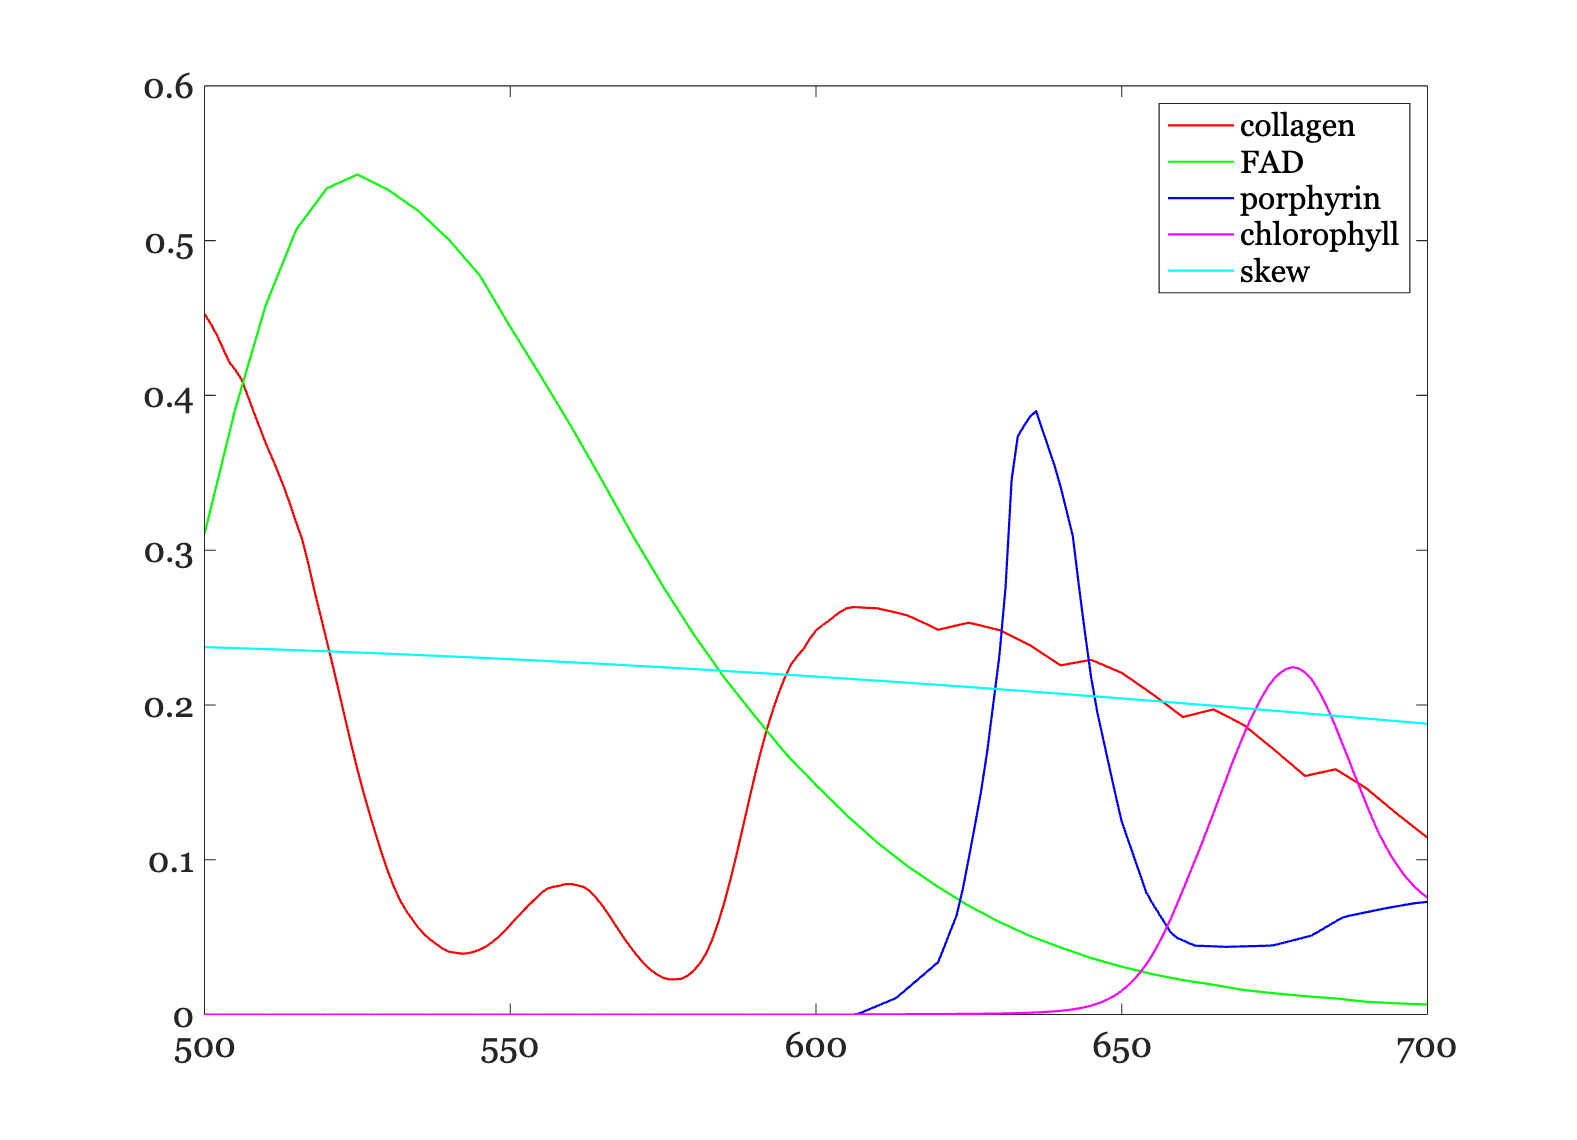

ieFigure;
plot(wave,finalFluorophores*diag(mean(weights,2)));
legend('collagen','FAD','porphyrin','chlorophyll','skew');

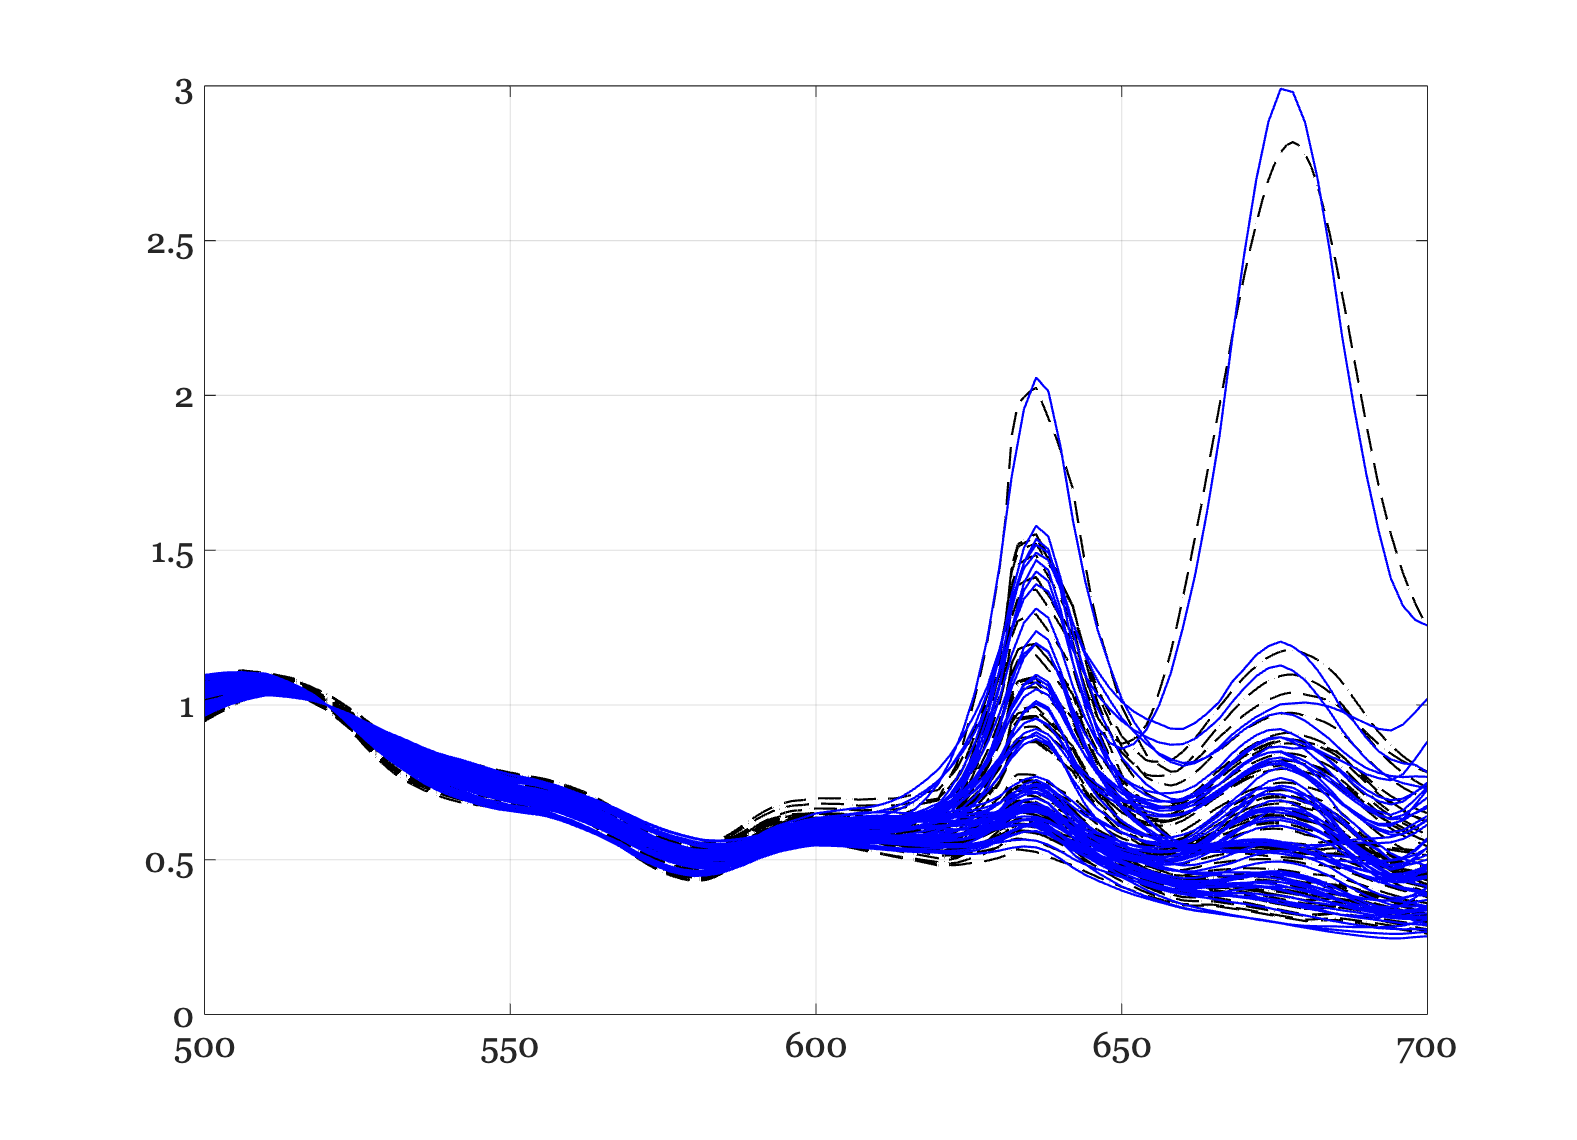

predicted = finalFluorophores*weights;
ieFigure; 
plot(wave,predicted,'k--'); hold on;
plot(wave,tongueData,'b-'); grid on;

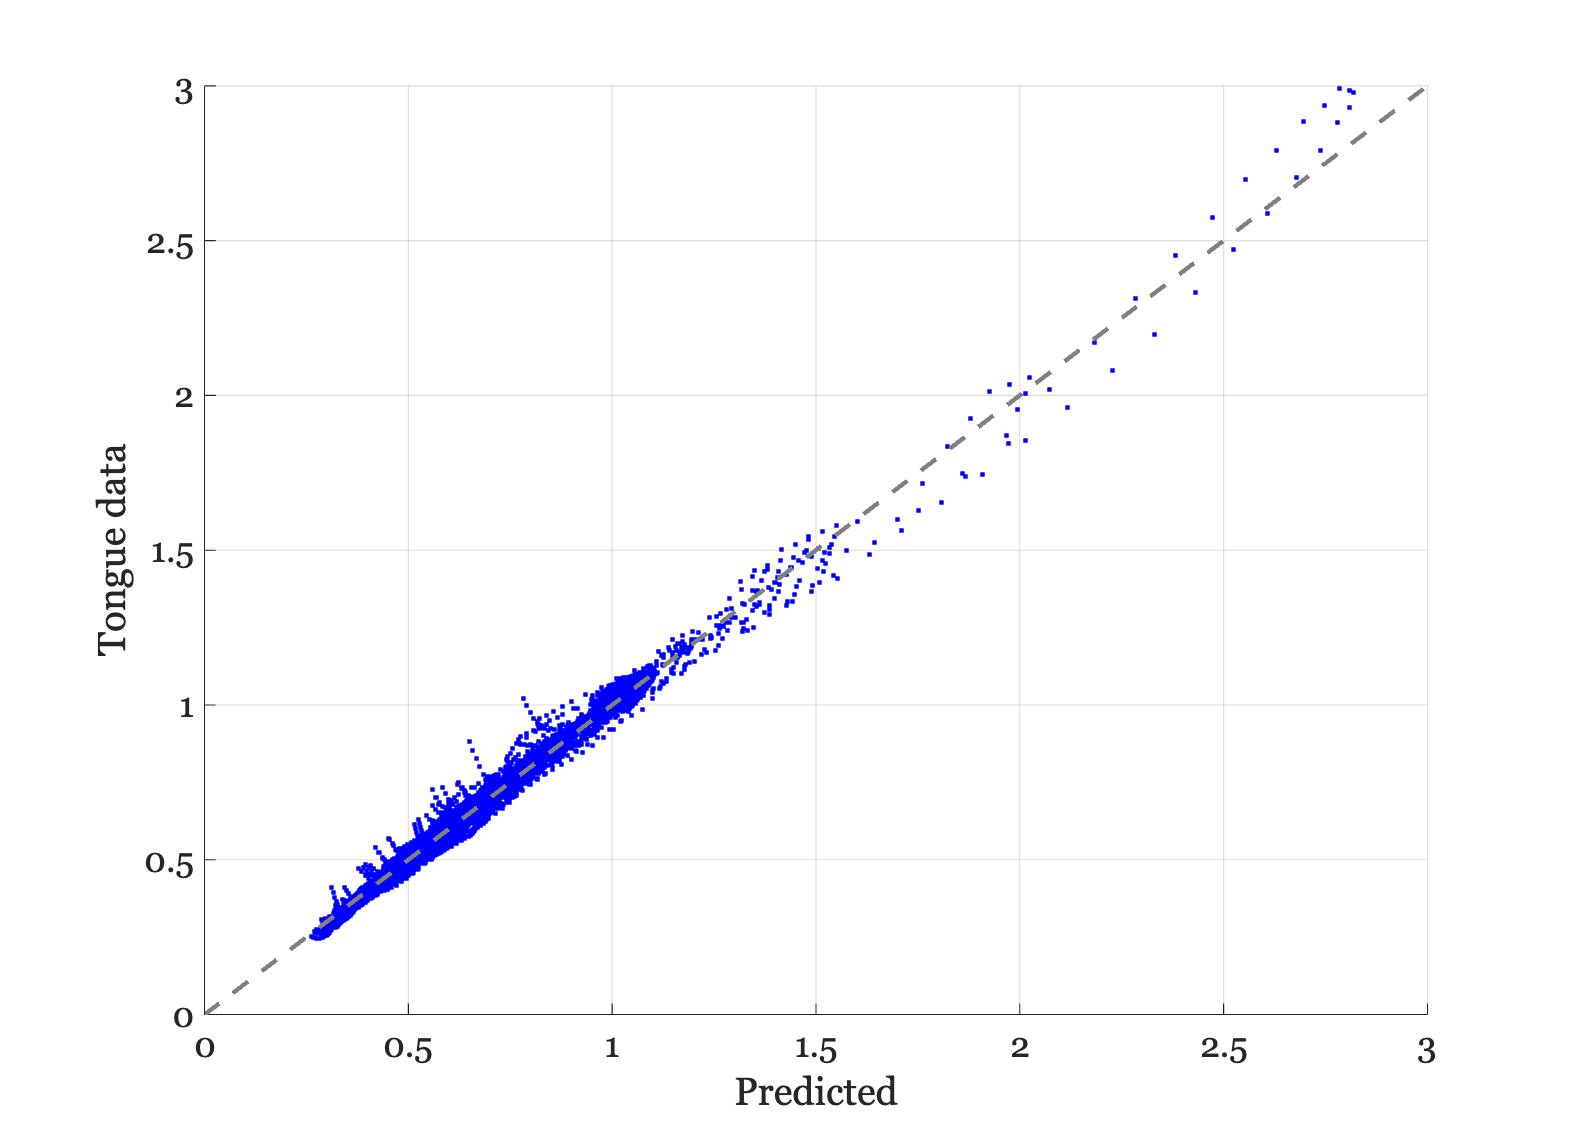

ieFigure;
scatter(predicted(:),tongueData(:),'b.'); 
xlabel('Predicted'); ylabel('Tongue data'); identityLine;

Here are the mean weights for the five different fluorophores when fit to the group tongue data.

mn = mean(weights,2);
fprintf('Collagen %.2f FAD %.2f Porphyrin %.2f Chlorophyll %0.2f PseudoKeratin %.2f\n',mn);

Collagen 10.43 FAD 0.54 Porphyrin 0.39 Chlorophyll 0.22 PseudoKeratin 0.30


## Fit the lip with a subset of fluorophores

We load all the lipData.

We fit them using only the first two columns of the fixed fluorophores.  We just solve for the blood applied to the first column.  This step is not necessary, but it was a good check that we could approximate the group with a single blood optical density.

lipData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    lipData = cat(2,lipData,tmp);
end

[od, weights,finalFluorophores] = oeSolveBlood(wave, lipData, fixedFluorophores(:,[1,2]));
fprintf('Blood density %.2f\n',od); ieFigure;

Blood density 8.63


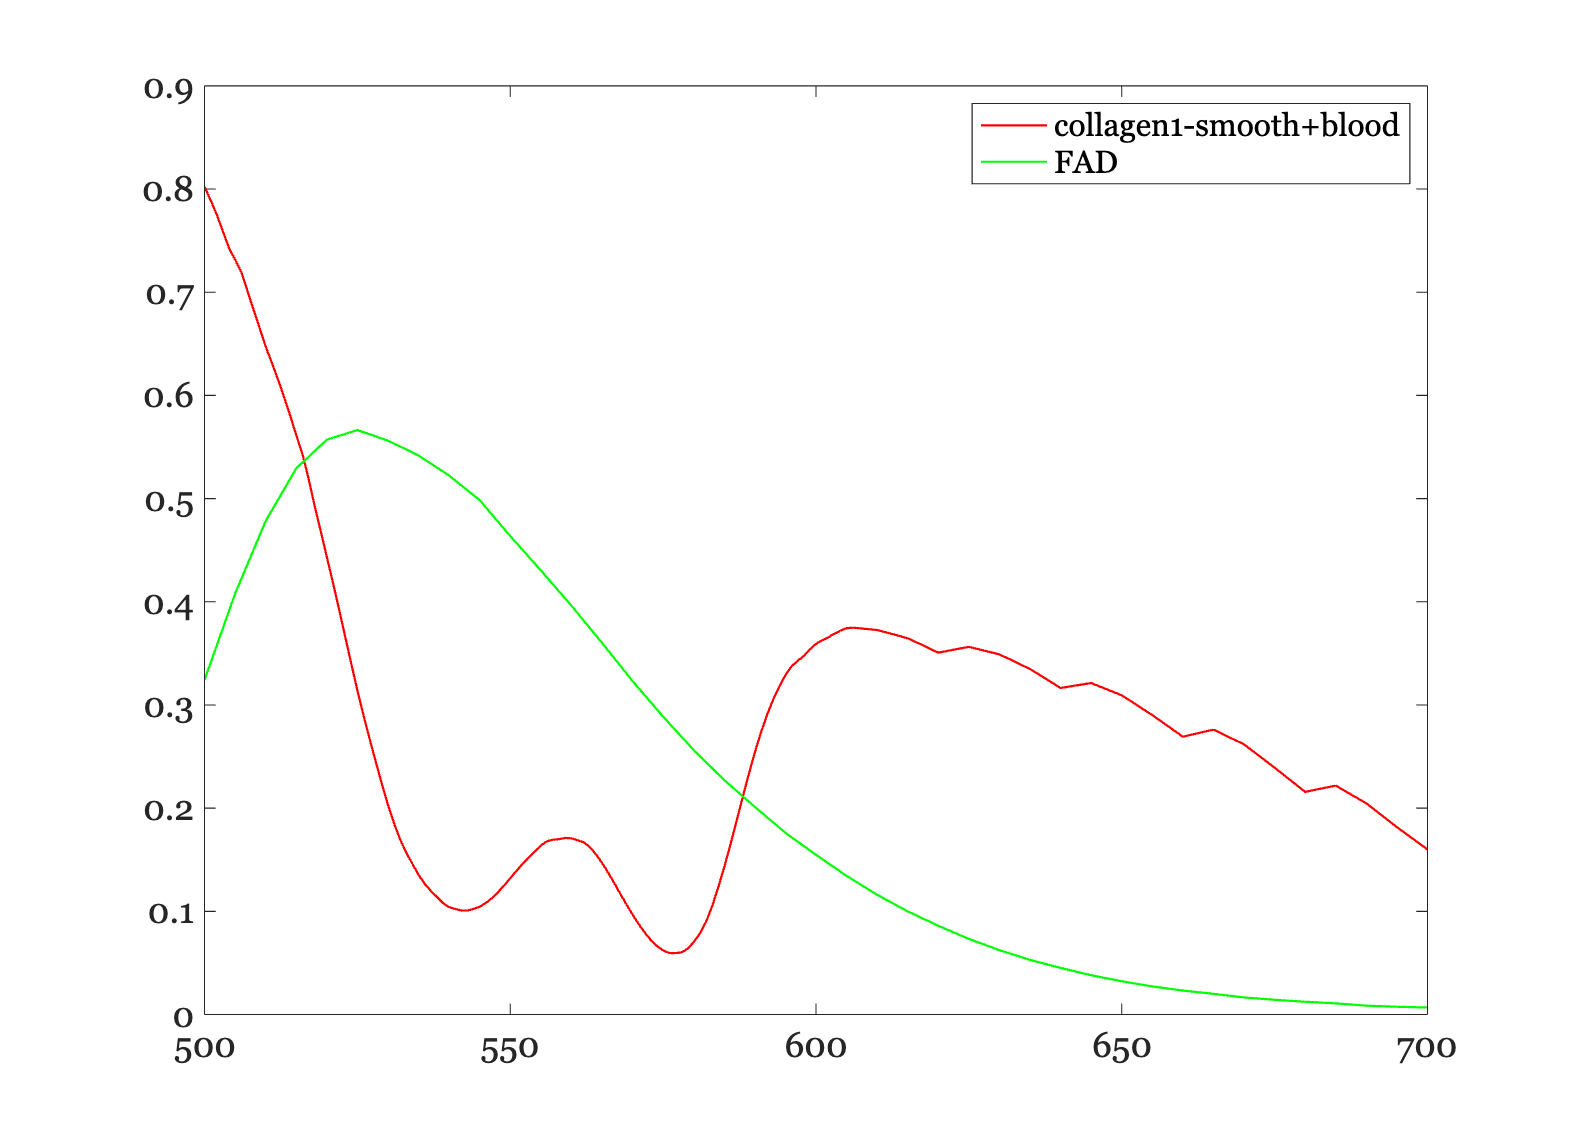

plot(wave,finalFluorophores*diag(mean(weights,2))); 
grid on; xlabel('Wavelength (nm)'); ylabel('Fluorescence');
legend('collagen1-smooth+blood','FAD');

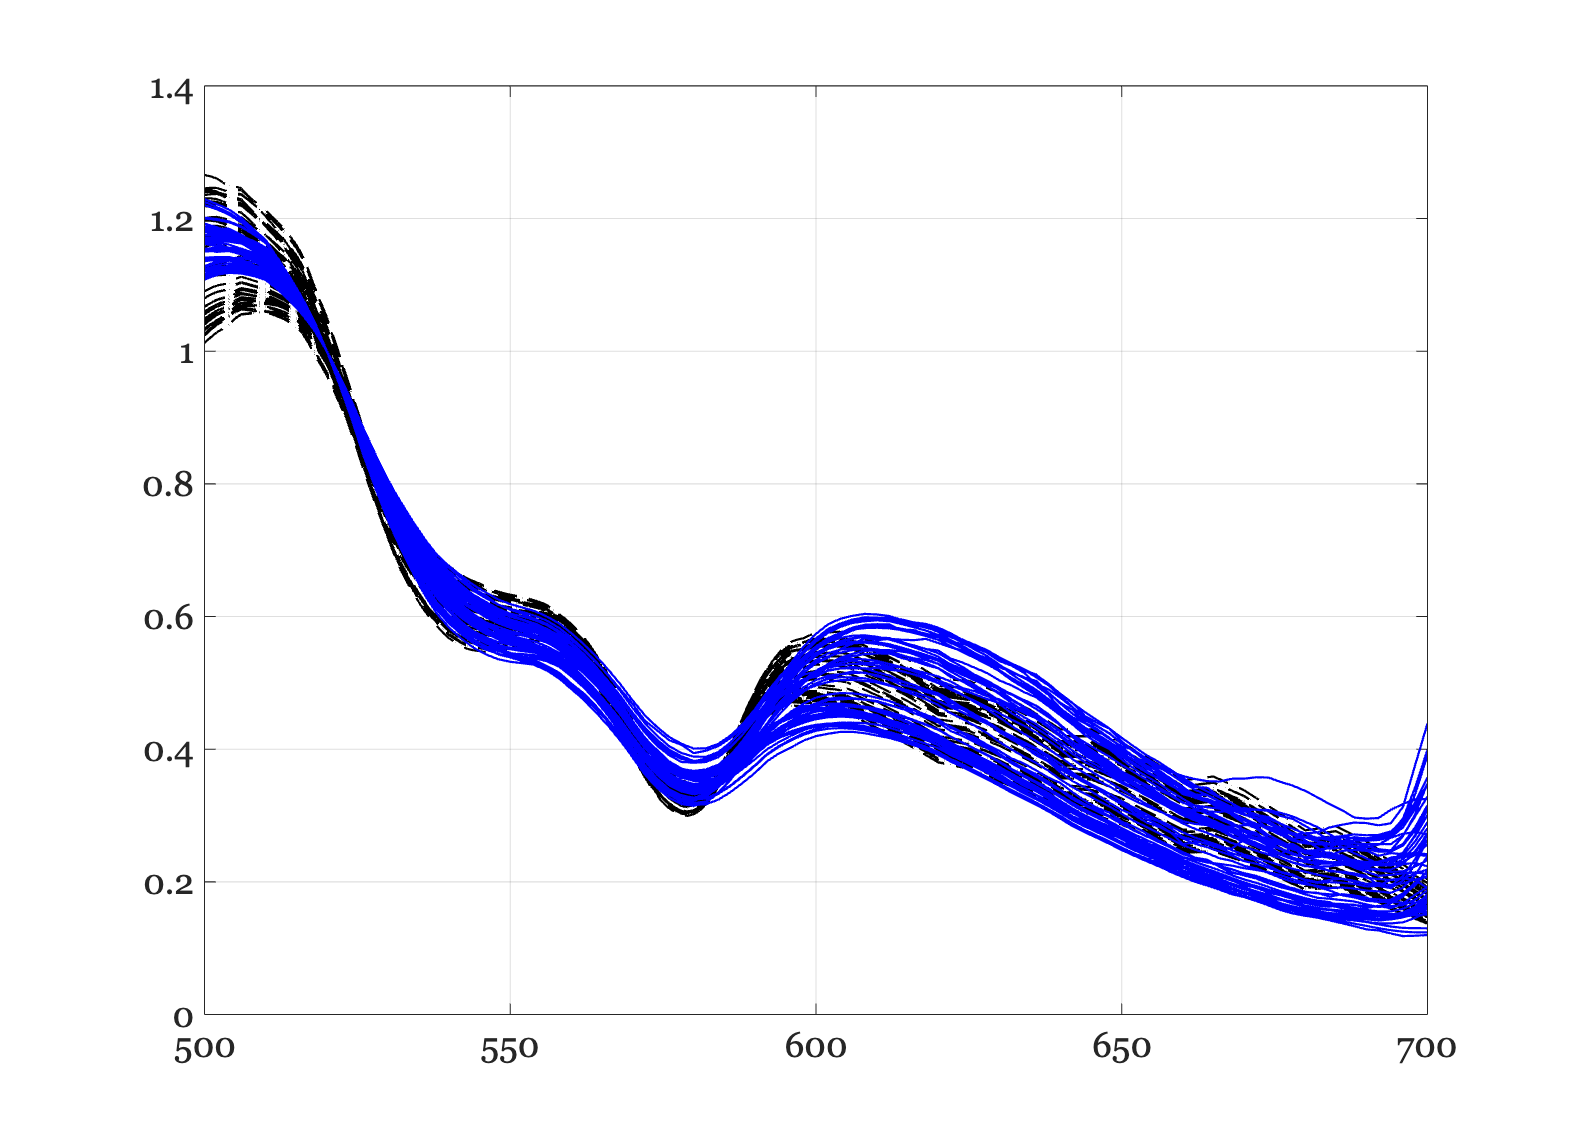

predicted = finalFluorophores*weights;
ieFigure; 
hA = plot(wave,predicted,'k--'); hold on;
hB = plot(wave,lipData,'b-'); grid on;

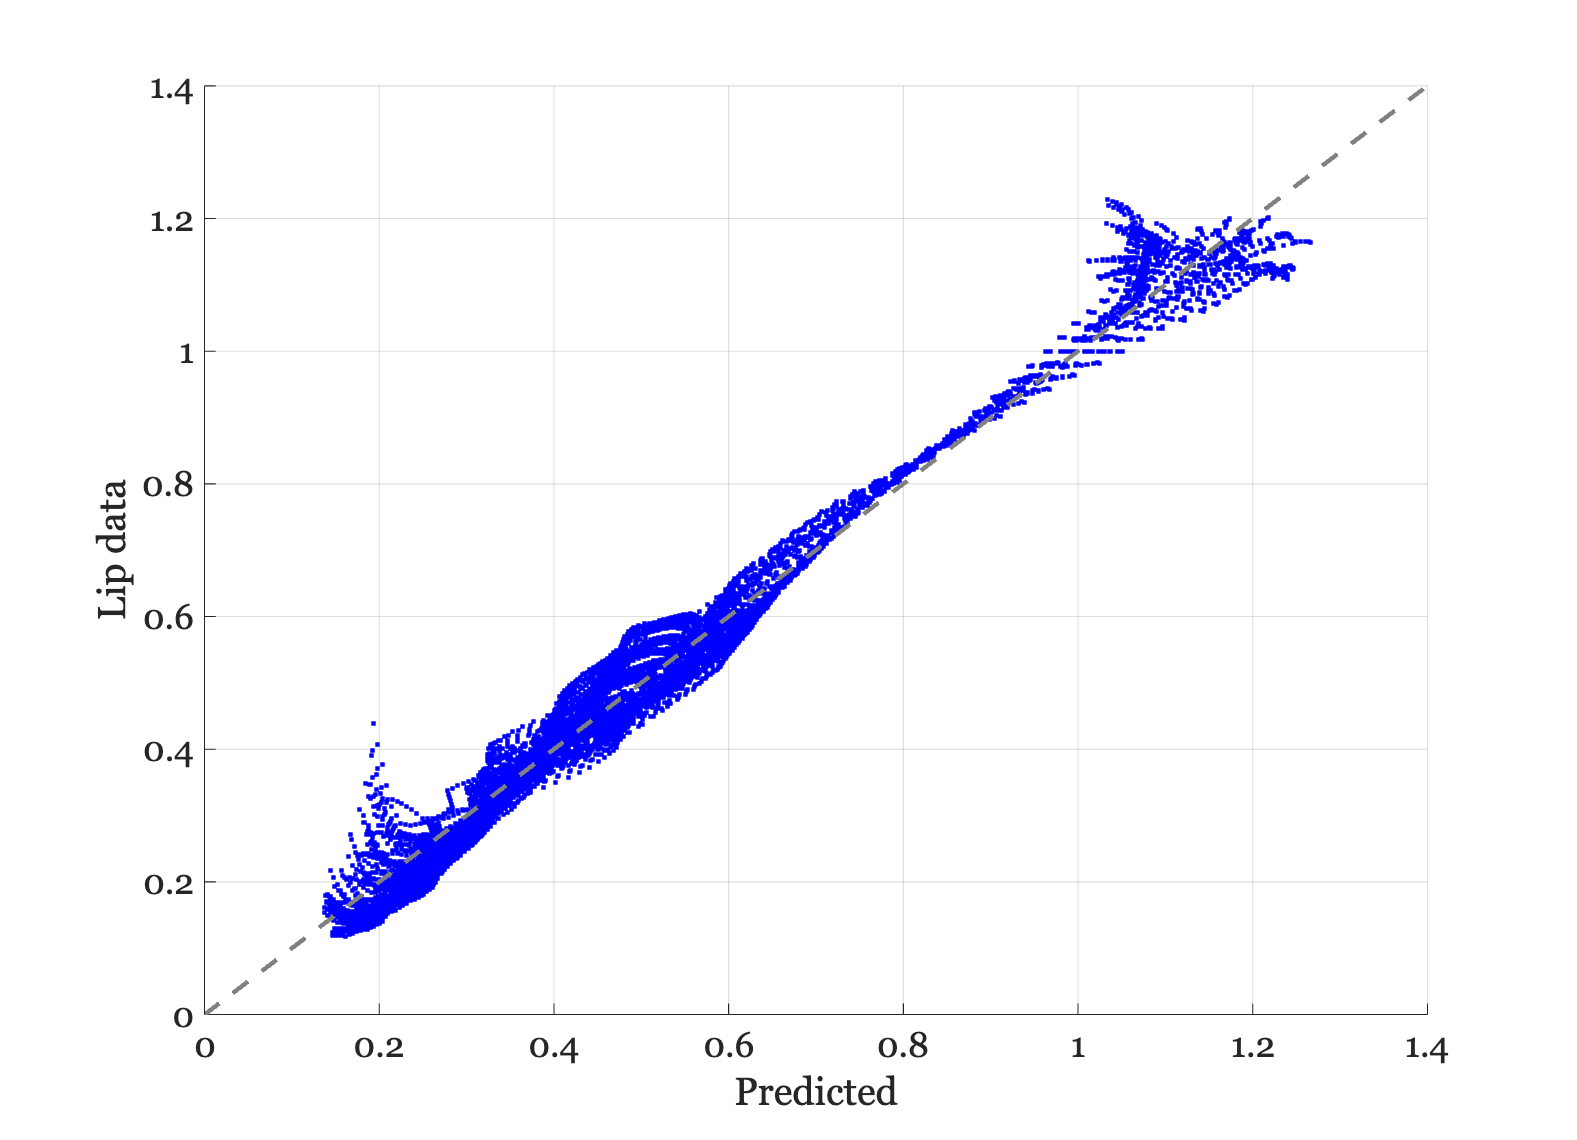

ieFigure;
scatter(predicted(:),lipData(:),'b.'); 
identityLine; xlabel('Predicted'); ylabel('Lip data');

## Fit the subjects individually

For each subject, the tongue data.  Use the five fluorophores to fit, adjusting only for the blood.

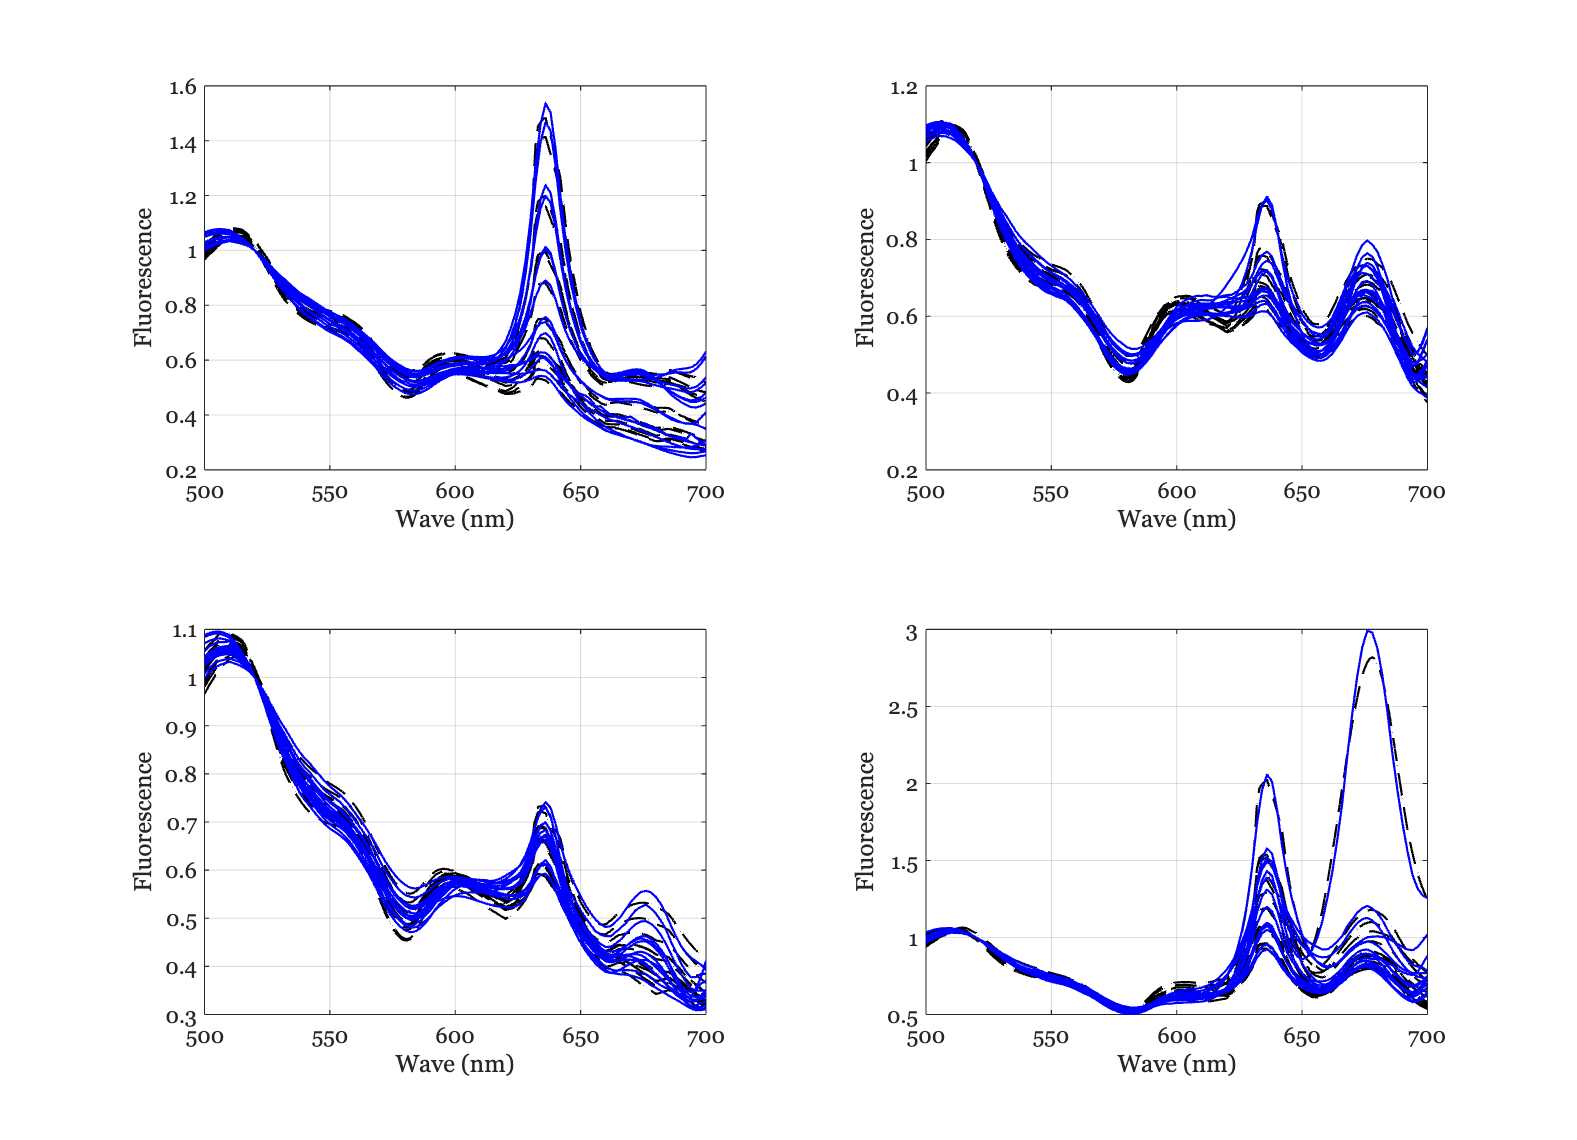

odTongue = zeros(1,numel(subjects));
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the tongue data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData  = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    % Find the blood optical density
    [odTongue(ii),weights,finalFluorophores] = oeSolveBlood(wave,tongueData,savedFluorophores);
    predicted = finalFluorophores*weights;
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,tongueData,'b-'); grid on;
    xlabel('Wave (nm)'); ylabel('Fluorescence');
end

## Fit the lip data

For the lip, we only fit using the collagen and FAD data, adjusting for the blood.  We omit the porphyrins, chlorophyll and pseudo-keratin.

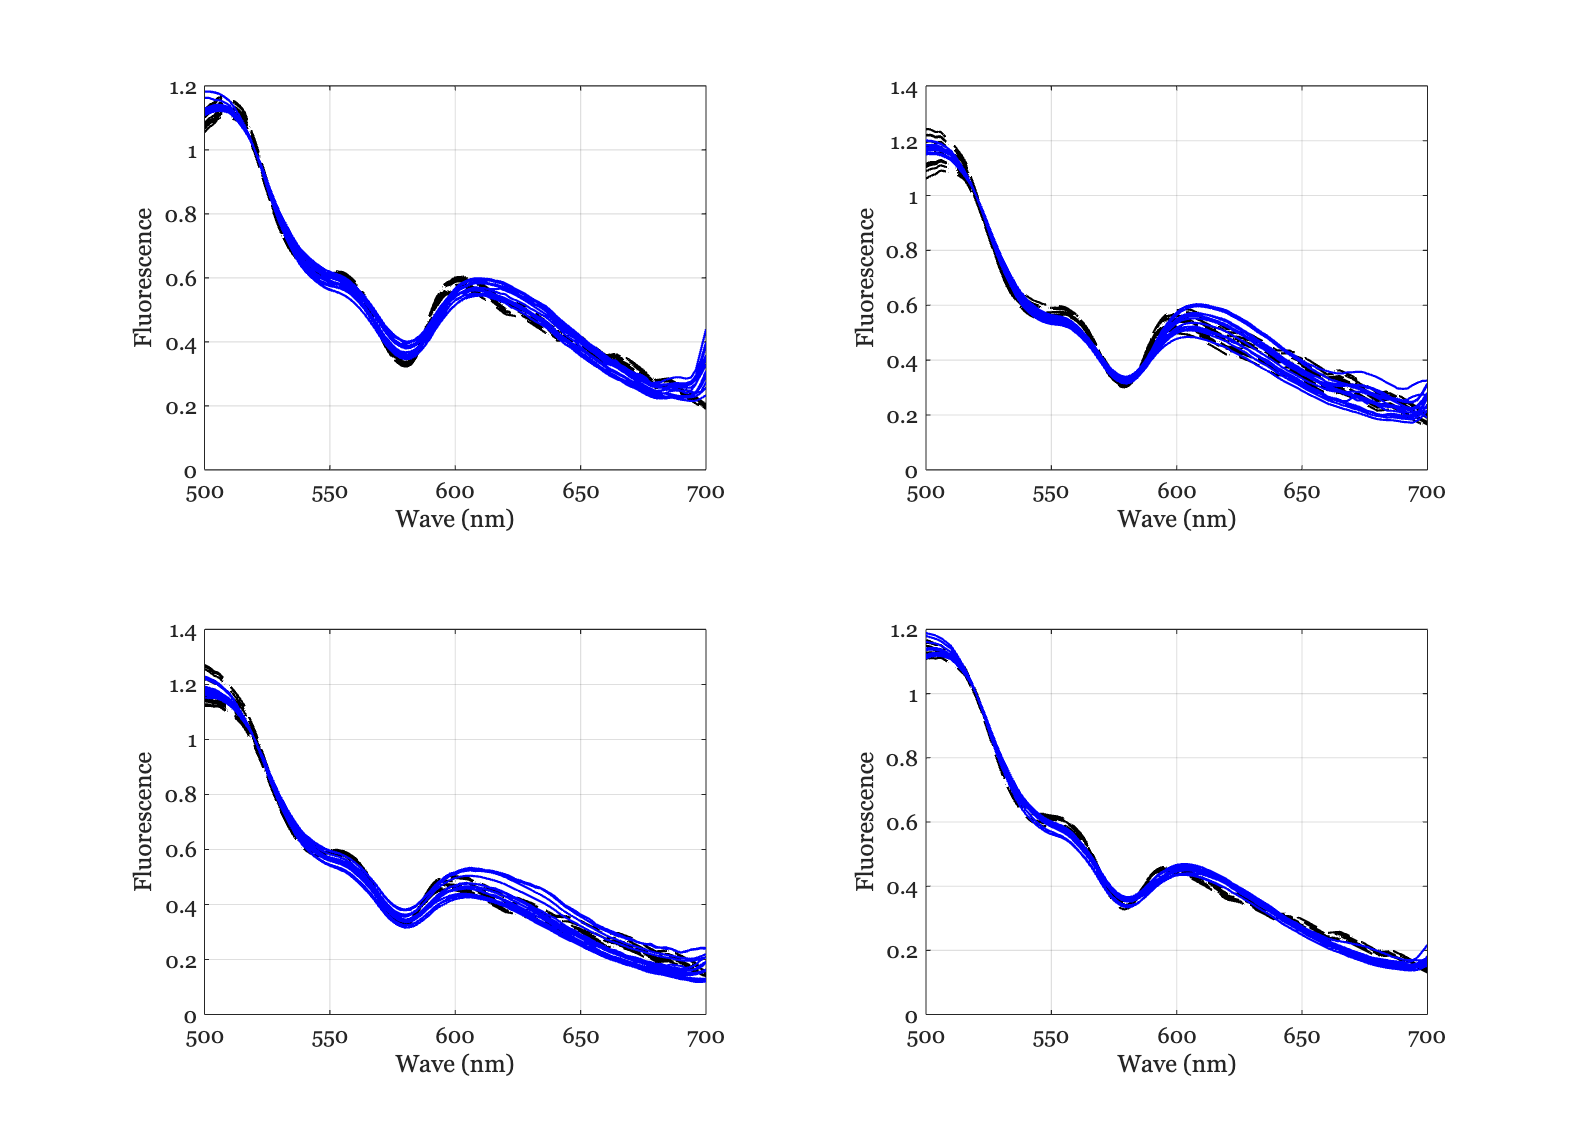

odLip = zeros(1,numel(subjects));
ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)   
    % Load the lip data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    [odLip(ii),weights,finalFluorophores] = oeSolveBlood(wave,lipData,savedFluorophores(:,[1,2]));
    predicted = finalFluorophores*weights;
    nexttile;
    plot(wave,predicted,'k--'); hold on;
    plot(wave,lipData,'b-'); grid on;
    xlabel('Wave (nm)'); ylabel('Fluorescence');
end

mn = mean(weights,2);
fprintf('Collagen %.2f FAD %.2f\n',mn);

Collagen 11.81 FAD 0.53


fprintf('Subjects lip optical densities %.2f\n',odLip);

Subjects lip optical densities 11.54
Subjects lip optical densities 9.13
Subjects lip optical densities 6.32
Subjects lip optical densities 5.97


fprintf('Subjects tongue optical densities %.2f\n',odTongue);

Subjects tongue optical densities 9.97
Subjects tongue optical densities 11.75
Subjects tongue optical densities 9.50
Subjects tongue optical densities 13.21
